# Determine Is from fit of the V(I)

clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\04_IV_curve_n2_max_b1.txt';

CONVERSION = 50e3;
if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/CONVERSION;   
end
Iraw = (Iraw + abs(Iraw(Vraw == 0)))*100; % To obtain A/cm2 (the cell is 1mm2)
Iraw(Vraw == 0)

ans = 0

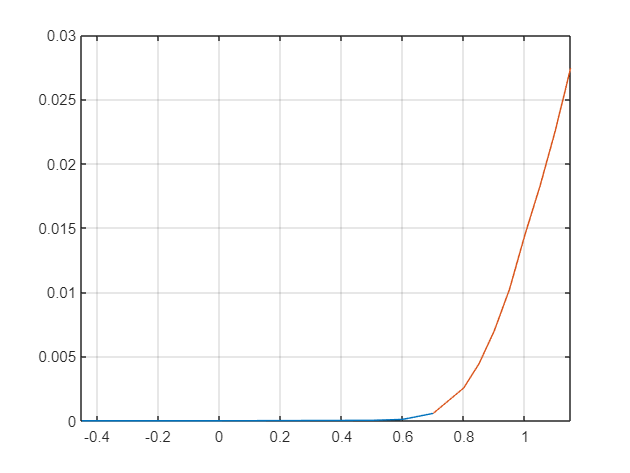

start = 5;
V = Vraw(start:end);
I = abs(Iraw(start:end));

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

N_IDEALITY_FACTOR = 2.12;
THERMAL_VOLTAGE_RT = 0.02585;
Rs0 = 0.37;
alpha0 = 15;
% Is0 = 1e-12;
Is0 = 80;
p0 = [Rs0, alpha0];
% T0 = 300/(alpha0*0.02585*2);
T0 = 300/(alpha0*THERMAL_VOLTAGE_RT*N_IDEALITY_FACTOR)

T0 = 364.9502

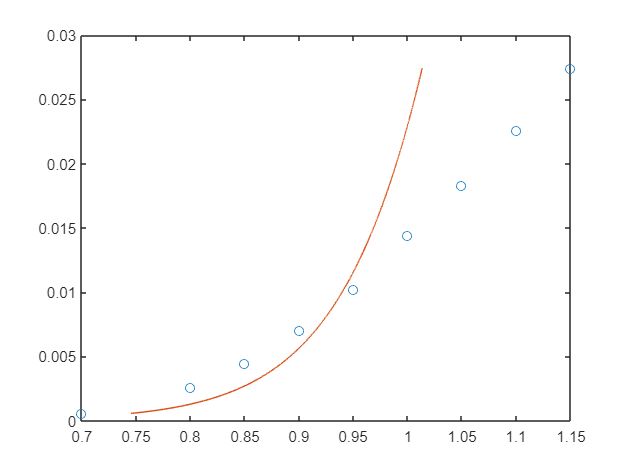

% T = 300/(alpha0*THERMAL_VOLTAGE_RT*n0)
% C(1) = Rs, C(2) = 1/alpha, C(3) = 1/Is
Vmodel = @(I, C, Is) C(1)*I + 1/C(2)*log(I/(Is*1e-10) + 1);

II = linspace(Iraw(start), Iraw(end), 10000);
figure()
plot(V, I, 'o')
hold on
plot(Vmodel(II, p0, Is0), II)

OptFit = optimset('display', 'off');
IsFit = lsqnonlin(@(p) V - Vmodell(V, I, p), Is0, [], [], OptFit)

IsFit = 80

[yfit, p] = Vmodell(V, I, IsFit);
p

p =     8.0445   16.2104


T = 300/(THERMAL_VOLTAGE_RT*p(2)*N_IDEALITY_FACTOR)

T = 337.7002

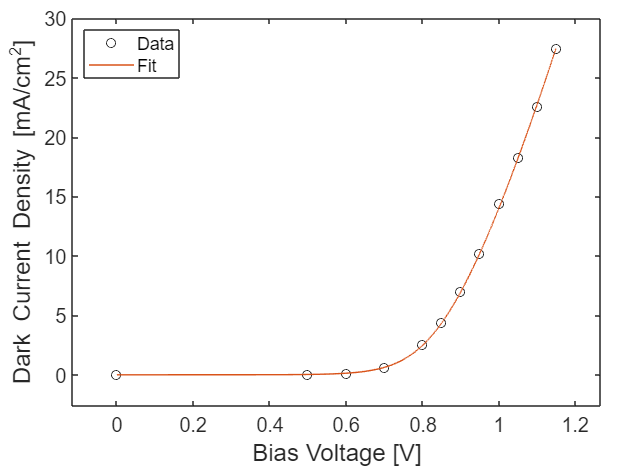

II = linspace(Iraw(1), Iraw(end), 10000);

f = figure();
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
ax = nexttile;
h(1) = plot(Vraw(2:end), Iraw(2:end)*1000, 'ko');
hold on
h(2) = plot(Vmodel(II, p, IsFit), II*1000);
xlim(setAxLim(Vraw(2:end), 0.1)); ylim(setAxLim(Iraw(2:end)*1000, 0.094));
lgd = legendFirstTile(tL, {'Data', 'Fit'});
lgd.Location = 'northwest';
labelAxesFig(tL, 'Bias Voltage [V]', 'Dark Current Density [mA/cm^2]')

exportFig(f, 'D:\Profile\qse\Files\_EDMRoC pinSC\Images', '\fit inverse IVcurve maxb1', 'pdf', 'IV curve')

Graphics not exported


exportFig(f, 'D:\Profile\qse\Files\_EDMRoC pinSC\Images', '\fit inverse IVcurve maxb1', 'png', 'IV curve')

Graphics not exported


function [Vfit, C] = Vmodell(V, I, Is)

VfitLog = log(I/(Is*1e-10) + 1);
XX = [I, VfitLog];
params = XX \ V;
C(1) = params(1); C(2) = 1/params(2);
Vfit = XX * params;
end